# Center of Mass Workshop

Gravity is a distributed force acting uniformly on all the mass within an object. For most purposes (i.e., when we don't need to consider deformation or breakage of an object) we can consider the entire gravitational force of the object to be acting upon the object at a single point:  this point is the center of mass (COM, also referred to as Center of Gravity). The COM is the point about which the gravitational torque is zero:  the balance point of an object.  This is extremely important for ducks...or any other object that we wish to sit upright while being acted upon by gravity, since if there is no net torque around the COM, the object will not rotate.

## COM of Systems of Discrete Objects [55 minutes]

Let's start by considering the COM for a collection of discrete, individual objects.  For a set of objects each of mass $m_i$ located at vector positions, $\mathbf{r}_i$, the center of mass of the set is defined to be:


$$
\mathbf{r}_{COM} = \frac{1}{\sum_i m_i} \sum_{i} m_i \mathbf{r}_i$$


This equation looks like an expression for a weighted average because the COM is the ***mass-weighted average position*** of an object or group of objects.

### Exercise 1

At the board, draw a picture and write a caption that uses an example to explain this mathematical definition.

#### Solution

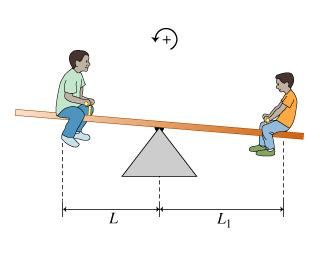

Two children of different mass balancing a seesaw by adjusting their distance from the fixed pivot point.

Lots of pictures could provide an excellent visual explanation of the mathematical definition for center of mass. The picture above is of two children of different masses on a seesaw. From intuition built on experience, we know that to balance the seesaw, the two children would have to sit different distances from the fixed pivot point. The mathematical definition of the COM is basically the inverse of this problem- for known positions and masses, where would the pivot point need to be placed in order to achieve the condition of perfect balance?

masses = [5 1];
positionsAlongBoard = [.2 -1];
teeterTotter(masses, positionsAlongBoard);

radiusAndHeight = 0.1168

radiusAndHeight = 0.0683

svc =   ServiceClient with properties:

    ServiceName: '/gazebo/delete_model'
    ServiceType: 'gazebo_msgs/DeleteModel'


ans =   ROS DeleteModelResponse message with properties:

      MessageType: 'gazebo_msgs/DeleteModelResponse'
          Success: 1
    StatusMessage: 'DeleteModel: successfully deleted model'

  Use showdetails to show the contents of the message


ans =   ROS SpawnModelResponse message with properties:

      MessageType: 'gazebo_msgs/SpawnModelResponse'
          Success: 1
    StatusMessage: 'SpawnModel: Successfully spawned entity'

  Use showdetails to show the contents of the message


% TODO: it would be cool to reposition the pivot, but it's not super
% straightforward (we might need an intermediate, massless link)

function teeterTotter(masses, positions)
% simulation of the teeter totter.  The masses are the massses of each object
% (or kid if you will) in kg.  The positions are the linear position along
% the beam in meters (valid positions are in the range of -3m,3m
doc = com.mathworks.xml.XMLUtils.createDocument('robot');

teeterTotterThickness = 0.1;
teeterTotterHeight = 0.75;
robotElem = doc.getDocumentElement();
robotElem.setAttribute('name','teeter_totter');
redBox(doc, 'pivot', 100, 0.1, 0.1, teeterTotterHeight);
redBox(doc, 'board', 1, 1, 4, teeterTotterThickness);

for i = 1 : length(masses)
    % mass = volume*density
    % volume = pi*r^3 (assume equal radius and height)
    % r = (mass/(pi*density))^(1/3)
    density = 1000; % assume 1000 kg/m^3 (density of water)
    radiusAndHeight = (masses(i)/(pi*density))^(1/3)
    blueCylinder(doc, ['weight_',num2str(i)], masses(i), radiusAndHeight, radiusAndHeight);
    connectWithFixedJoint(doc, ['weight_',num2str(i),'_joint'], 'board', ['weight_',num2str(i)], 0, positions(i), teeterTotterThickness);
end
connectWithContinuousJoint(doc, 'pivotlink', 'pivot', 'board', 0, 0, teeterTotterHeight);
spawnModel('teeter_totter',xmlwrite(robotElem),0,0,0);
end
